# Assignment 2

## initialize

close all;
clc

## 1. parameters

% physical params
g = 9.8

g = 9.8000


% vehicle params
weight = 1807.2 % kg

weight = 1.8072e+03

wheelbase = 2950*10^-3 % mm->m

wheelbase = 2.9500

R_tire = 402*10^-3 % mm->m

R_tire = 0.4020

beta_1 = 3.538

beta_1 = 3.5380

beta_2 = 2.06

beta_2 = 2.0600

beta_3 = 1.404

beta_3 = 1.4040

beta_4 = 1

beta_4 = 1

beta_5 = 0.713

beta_5 = 0.7130

beta_6 = 0.582

beta_6 = 0.5820

beta_dif = 4.1

beta_dif = 4.1000


% engine params
speed_max = 6700 % rpm

speed_max = 6700

speed_min = 725 % rpm

speed_min = 725

omega_max = speed_max*0.1047198 % rpm->rad/s

omega_max = 701.6227

omega_min = speed_min*0.1047198 % rpm->rad/s, idle

omega_min = 75.9219


yita_d = 1 % differencial efficiency

yita_d = 1

yita_g = 1 % gear box efficiency

yita_g = 1


% resistance params
%%%%%%%%%%%%%%%%%%%%% it hasn't been done yet%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
mu_R = 1

mu_R = 1

gradient = 0

gradient = 0

A = 3 % m^2

A = 3

rho = 0.1

rho = 0.1000

c_d = 0.5% drag coefficient

c_d = 0.5000


% simulation params
dt = 0.01 % s

dt = 0.0100

### formulation

#### resistance formulation

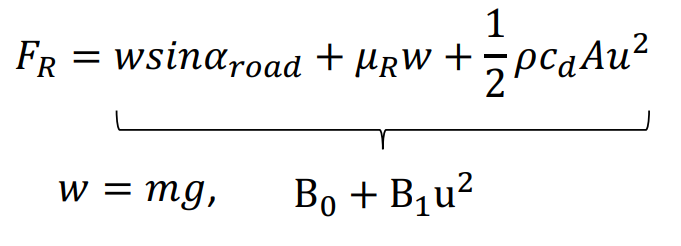

B0 = weight * g * sin(alpha) + mu_R * weight

B0 = 1.8072e+03

B1 = 0.5 * rho * c_d * A

B1 = 0.0750

## torque engine speed

### map

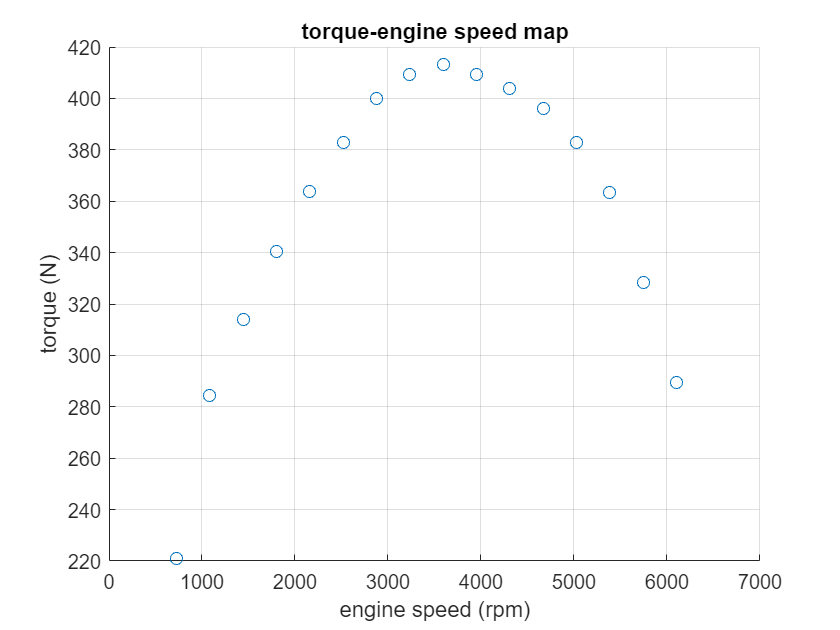

% the data is extracted from the carsim
% map_engine_spped = [400 508 617 725 1083 1442 1800 2158 2517 2875 3233 3592 3950 4308 4667 5025 5383 5742 6100 6500 6700];
% map_torque = [0 140.57 202.03 221.15 284.38 314.16 340.56 363.84 382.8 399.96 409.2 413.16 409.2 403.84 396 382.8 363.32 328.55 289.4 -106.92 -108.24];
map_engine_spped = [725 1083 1442 1800 2158 2517 2875 3233 3592 3950 4308 4667 5025 5383 5742 6100];
map_torque = [221.15 284.38 314.16 340.56 363.84 382.8 399.96 409.2 413.16 409.2 403.84 396 382.8 363.32 328.55 289.4];
scatter(map_engine_spped,map_torque)
title("torque-engine speed map");
xlabel("engine speed (rpm)");
ylabel("torque (N)");
grid on;

### poly fit

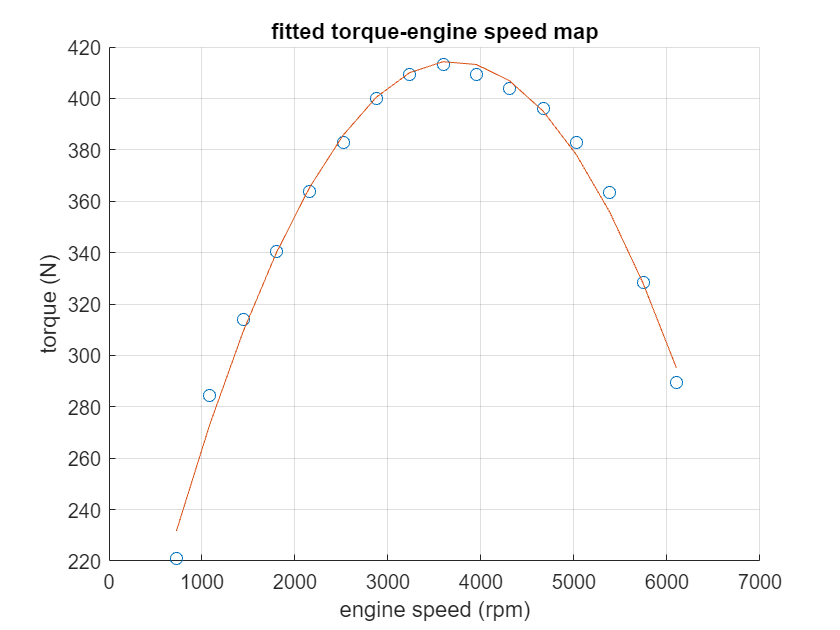

[p,ErrorEst] = polyfit(map_engine_spped,map_torque,2);
hold on;
title("fitted torque-engine speed map");
pop_fit = polyval(p,map_engine_spped,ErrorEst);
plot(map_engine_spped,pop_fit)

## torque engine speed map with different gear box

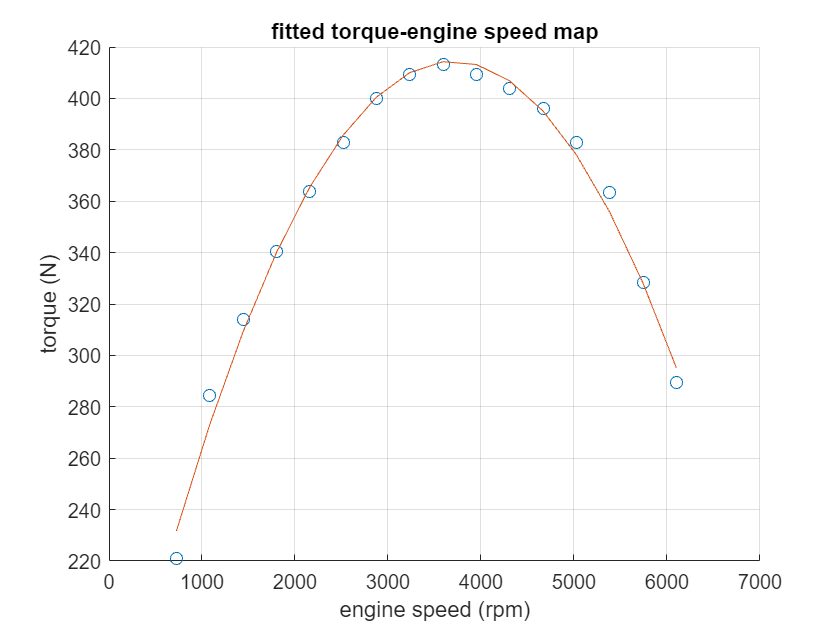

hold off;

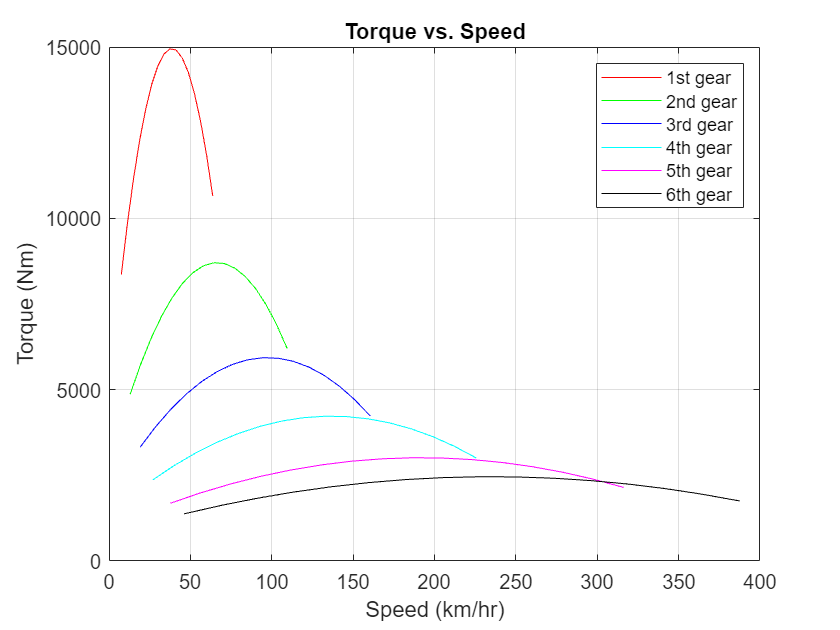

% calculate the torque of each gear
x1 = map_engine_spped / beta_dif / beta_1 * R_tire * 2 * pi * 3.6 / 60;
y1 = beta_dif * beta_1 / R_tire * polyval(p, map_engine_spped, ErrorEst);
x2 = map_engine_spped / beta_dif / beta_2 * R_tire * 2 * pi * 3.6 / 60;
y2 = beta_dif * beta_2 / R_tire * polyval(p, map_engine_spped, ErrorEst);
x3 = map_engine_spped / beta_dif / beta_3 * R_tire * 2 * pi * 3.6 / 60;
y3 = beta_dif * beta_3 / R_tire * polyval(p, map_engine_spped, ErrorEst);
x4 = map_engine_spped / beta_dif / beta_4 * R_tire * 2 * pi * 3.6 / 60;
y4 = beta_dif * beta_4 / R_tire * polyval(p, map_engine_spped, ErrorEst);
x5 = map_engine_spped / beta_dif / beta_5 * R_tire * 2 * pi * 3.6 / 60;
y5 = beta_dif * beta_5 / R_tire * polyval(p, map_engine_spped, ErrorEst);
x6 = map_engine_spped / beta_dif / beta_6 * R_tire * 2 * pi * 3.6 / 60;
y6 = beta_dif * beta_6 / R_tire * polyval(p, map_engine_spped, ErrorEst);

plot(x1, y1, 'r', x2, y2, 'g', x3, y3, 'b', x4, y4, 'c', x5, y5, 'm', x6, y6, 'k');
legend('1st gear', '2nd gear', '3rd gear', '4th gear', '5th gear', '6th gear');
title('Torque vs. Speed');
xlabel('Speed (km/hr)');
ylabel('Torque (Nm)');
grid on;